%--------------------------------%
%------------ Import ------------%
%--------------------------------%

format("shortG")

data5C_1 = importdata("Christoffer\P3\1.cyklus\Log Data 17-04-2023 12.27.24.txt").data(:,2);
data5C_2 = importdata("Christoffer\P3\2.cyklus\Log Data 17-04-2023 16.11.09.txt").data(:,2);
data5C_3 = importdata("Christoffer\P3\3.cyklus\Log Data 17-04-2023 20.05.37.txt").data(:,2);

data10C_1_up = importdata("Christoffer\P3\1.cyklus\Log Data 17-04-2023 12.54.19.txt").data(:,2);
data10C_2_up = importdata("Christoffer\P3\2.cyklus\Log Data 17-04-2023 16.54.32.txt").data(:,2);
data10C_3_up = importdata("Christoffer\P3\3.cyklus\Log Data 17-04-2023 20.34.42.txt").data(:,2);

data25C_1_up = importdata("Christoffer\P3\1.cyklus\Log Data 17-04-2023 13.22.15.txt").data(:,2);
data25C_2_up = importdata("Christoffer\P3\2.cyklus\Log Data 17-04-2023 17.27.51.txt").data(:,2);
data25C_3_up = importdata("Christoffer\P3\3.cyklus\Log Data 17-04-2023 21.02.25.txt").data(:,2);

data40C_1 = importdata("Christoffer\P3\1.cyklus\Log Data 17-04-2023 13.52.30.txt").data(:,2);
data40C_2 = importdata("Christoffer\P3\2.cyklus\Log Data 17-04-2023 17.57.29.txt").data(:,2);
data40C_3 = importdata("Christoffer\P3\3.cyklus\Log Data 17-04-2023 21.34.34.txt").data(:,2);

data25C_1_down = importdata("Christoffer\P3\1.cyklus\Log Data 17-04-2023 14.33.43.txt").data(:,2);
data25C_2_down = importdata("Christoffer\P3\2.cyklus\Log Data 17-04-2023 18.44.05.txt").data(:,2);
data25C_3_down = importdata("Christoffer\P3\3.cyklus\Log Data 17-04-2023 22.33.53.txt").data(:,2);

data10C_1_down = importdata("Christoffer\P3\1.cyklus\Log Data 17-04-2023 15.20.19.txt").data(:,2);
data10C_2_down = importdata("Christoffer\P3\2.cyklus\Log Data 17-04-2023 19.35.12.txt").data(:,2);
data10C_3_down = importdata("Christoffer\P3\3.cyklus\Log Data 18-04-2023 08.48.40.txt").data(:,2);

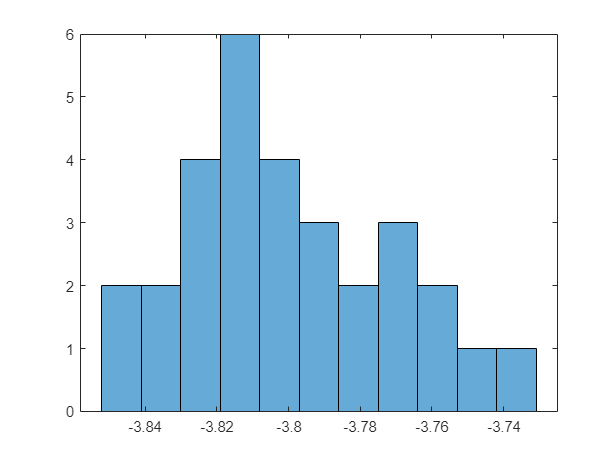



%--------------------------------%
%-------- Temp Convert ----------%
%--------------------------------%
A = 5.11*1e-4; 
B = 3.717*1e-4; 
C = -1.278*1e-5;
D = 6.441*1e-7;

n = 3;



eq = @(rs) 1./(A + B*log(rs) + C*log(rs).^(n-1) + D*log(rs).^n) - 273.15;

data5C_1_temp = eq(data5C_1);
data5C_2_temp = eq(data5C_2);
data5C_3_temp = eq(data5C_3);


data10C_1_up_temp = eq(data10C_1_up);
data10C_2_up_temp = eq(data10C_2_up);
data10C_3_up_temp = eq(data10C_3_up);

data25C_1_up_temp = eq(data25C_1_up);
data25C_2_up_temp = eq(data25C_2_up);
data25C_3_up_temp = eq(data25C_3_up);

data40C_1_up_temp = eq(data40C_1);
data40C_2_up_temp = eq(data40C_2);
data40C_3_up_temp = eq(data40C_3);

data25C_1_down_temp = eq(data25C_1_down);
data25C_2_down_temp = eq(data25C_2_down);
data25C_3_down_temp = eq(data25C_3_down);

data10C_1_down_temp = eq(data10C_1_down);
data10C_2_down_temp = eq(data10C_2_down);
data10C_3_down_temp = eq(data10C_3_down);

temp_array = [data5C_1_temp, data5C_2_temp, data5C_3_temp, data10C_1_up_temp, data10C_2_up_temp, data10C_3_up_temp, data25C_1_up_temp, data25C_2_up_temp, data25C_3_up_temp, data40C_1_up_temp, data40C_2_up_temp, data40C_3_up_temp, data25C_1_down_temp, data25C_2_down_temp, data25C_3_down_temp, data10C_1_down_temp, data10C_2_down_temp, data10C_3_down_temp];
%--------------------------------%
%------------- tid --------------%
%--------------------------------%

t_pr_mean = 3000000 / 30 / 10000;
t = 0:10:10*29;


%--------------------------------%
%---------- modeller ------------%
%--------------------------------%

mdl_5C_1 = fitlm(t,data5C_1_temp);
mdl_5C_1.Coefficients.Estimate(1)

ans =       -3.8025


mdl_5C_1.Coefficients.Estimate(2)

ans =    2.2697e-05


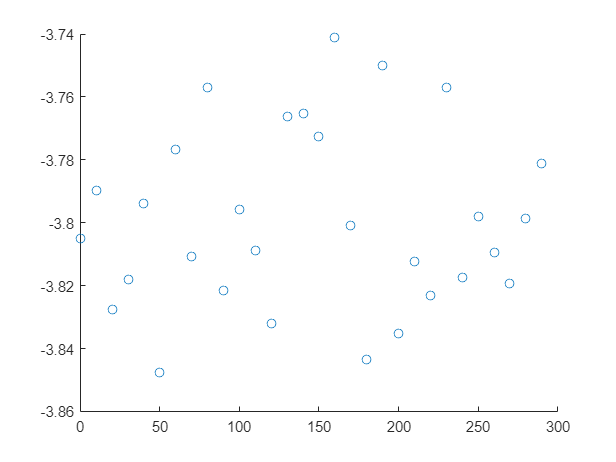

mdl_5C_2 = fitlm(t,data5C_2_temp);
mdl_5C_3 = fitlm(t,data5C_3_temp);

mdl_10C_up_1 = fitlm(t,data10C_1_up_temp);
mdl_10C_up_2 = fitlm(t,data10C_2_up_temp);
mdl_10C_up_3 = fitlm(t,data10C_3_up_temp);

mdl_25C_up_1 = fitlm(t,data25C_1_up_temp);
mdl_25C_up_2 = fitlm(t,data25C_2_up_temp);
mdl_25C_up_3 = fitlm(t,data25C_3_up_temp);

mdl_40C_1 = fitlm(t,data40C_1);
mdl_40C_2 = fitlm(t,data40C_2);
mdl_40C_3 = fitlm(t,data40C_3);

mdl_25C_ned_1 = fitlm(t,data5C_1_temp);
mdl_25C_ned_2 = fitlm(t,data5C_2_temp);
mdl_25C_ned_3 = fitlm(t,data5C_3_temp);

mdl_10C_ned_1 = fitlm(t,data5C_1_temp);
mdl_10C_ned_2 = fitlm(t,data5C_2_temp);
mdl_10C_ned_3 = fitlm(t,data5C_3_temp);

scatter(t,data5C_1_temp)

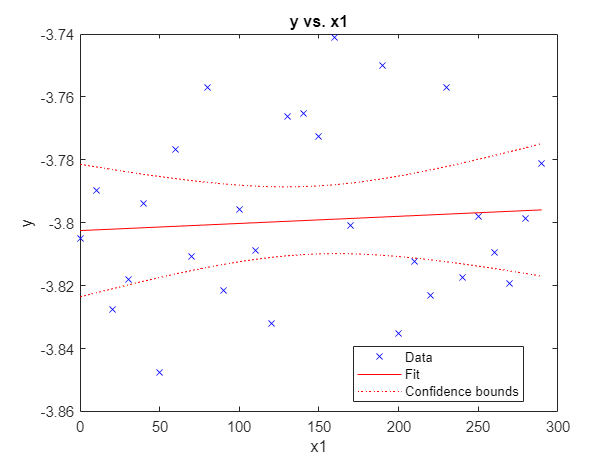


plot(mdl_5C_1)

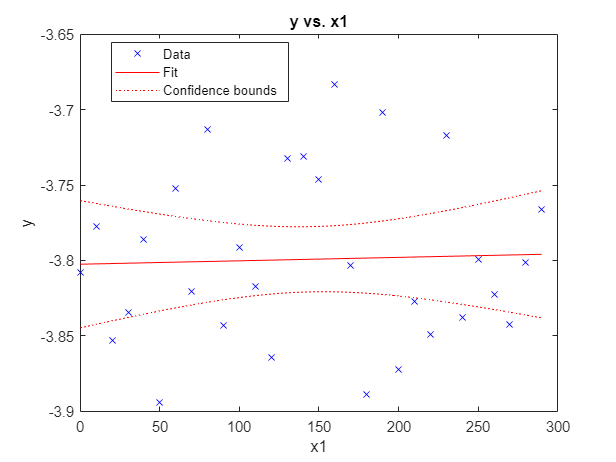


%--------------------------------%
%-------- korttidsdrift ---------%
%--------------------------------%

syms x y
f(x) = -3.8025 + x * 2.2697e-05;

%--------------------------------%
%---------- stabilitet ----------%
%--------------------------------%

stab_5C_1_affektor = vpa(data5C_1_temp - f(t'), 10);
stab_5C_1 = data5C_1_temp + stab_5C_1_affektor;
stab_5C_1 = double(stab_5C_1);
mdl_5C_1_2 = fitlm(t,stab_5C_1);
plot(mdl_5C_1_2)

std(stab_5C_1)

ans =      0.056804



stab_array = [];
kort_array = [];

for i=1:18
    [korttids, stab] = STAT.P3_ussikerhed(temp_array(:,i), t);
    stab_array(end+1) = stab;
    kort_array(end+1) = korttids;
end

mdl_5C_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)       -3.8025       0.01029    -369.54    3.4581e-53
    x1             2.2697e-05    6.0933e-05    0.37249       0.71233


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.0289
R-squared: 0.00493,  Adjusted R-Squared: -0.0306
F-statistic vs. constant model: 0.139, p-value = 0.712

mdl_5C_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)        -3.6414      0.037274     -97.691    5.0303e-37
    x1             -0.00019835    0.00022073    -0.89859       0.37654


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.105
R-squared: 0.028,  Adjusted R-Squared: -0.00668
F-statistic vs. constant model: 0.807, p-value = 0.377

mdl_5C_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)      -3.8308     0.0098531    -388.79    8.3466e-54
    x1             4.889e-05    5.8347e-05    0.83792       0.40917


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.0277
R-squared: 0.0245,  Adjusted R-Squared: -0.0104
F-statistic vs. constant model: 0.702, p-value = 0.409

mdl_5C_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE         tStat       pValue  
                   ___________    __________    _______    __________

    (Intercept)         11.091     0.0079733       1391    2.6403e-69
    x1             -0.00011033    4.7216e-05    -2.3366       0.02684


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.0224
R-squared: 0.163,  Adjusted R-Squared: 0.133
F-statistic vs. constant model: 5.46, p-value = 0.0268

mdl_5C_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)        11.027      0.006738    1636.6    2.7812e-71
    x1             0.00010938    3.9901e-05    2.7413      0.010539


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.0189
R-squared: 0.212,  Adjusted R-Squared: 0.183
F-statistic vs. constant model: 7.51, p-value = 0.0105

mdl_5C_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)         10.997     0.0064112      1715.3    7.4657e-72
    x1             -1.0694e-05    3.7966e-05    -0.28168       0.78026


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.018
R-squared: 0.00283,  Adjusted R-Squared: -0.0328
F-statistic vs. constant model: 0.0793, p-value = 0.78

mdl_5C_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)         25.73     0.0064307    4001.1    3.7468e-82
    x1             5.7575e-05    3.8081e-05    1.5119       0.14176


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.0181
R-squared: 0.0755,  Adjusted R-Squared: 0.0425
F-statistic vs. constant model: 2.29, p-value = 0.142

mdl_5C_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)        25.709     0.0068728     3740.7    2.4662e-81
    x1             1.6908e-05    4.0699e-05    0.41544       0.68099


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.0193
R-squared: 0.00613,  Adjusted R-Squared: -0.0294
F-statistic vs. constant model: 0.173, p-value = 0.681

mdl_5C_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)        25.709     0.0050587    5082.1    4.6292e-85
    x1             4.7992e-05    2.9956e-05    1.6021       0.12036


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.0142
R-squared: 0.084,  Adjusted R-Squared: 0.0513
F-statistic vs. constant model: 2.57, p-value = 0.12

mdl_5C_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE         tStat        pValue  
                   ___________    _________    ________    __________

    (Intercept)         40.327    0.0052721      7649.2    4.9361e-90
    x1             -9.4028e-06    3.122e-05    -0.30118        0.7655


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.0148
R-squared: 0.00323,  Adjusted R-Squared: -0.0324
F-statistic vs. constant model: 0.0907, p-value = 0.766

mdl_5C_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE         tStat       pValue  
                   ___________    __________    _______    __________

    (Intercept)         40.327     0.0036867      10938    2.2078e-94
    x1             -3.7754e-05    2.1832e-05    -1.7293      0.094768


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.0104
R-squared: 0.0965,  Adjusted R-Squared: 0.0642
F-statistic vs. constant model: 2.99, p-value = 0.0948

mdl_5C_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)        40.333      0.005811    6940.8    7.5043e-89
    x1             8.3598e-05    3.4412e-05    2.4294      0.021795


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.0163
R-squared: 0.174,  Adjusted R-Squared: 0.145
F-statistic vs. constant model: 5.9, p-value = 0.0218

mdl_5C_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)         25.77     0.0059076    4362.1    3.3355e-83
    x1             3.9412e-05    3.4984e-05    1.1266       0.26948


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.0166
R-squared: 0.0434,  Adjusted R-Squared: 0.0092
F-statistic vs. constant model: 1.27, p-value = 0.269

mdl_5C_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)         25.729     0.0060105      4280.7    5.6545e-83
    x1             -3.9126e-06    3.5593e-05    -0.10993       0.91325


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.0169
R-squared: 0.000431,  Adjusted R-Squared: -0.0353
F-statistic vs. constant model: 0.0121, p-value = 0.913

mdl_5C_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)        25.756     0.0054575    4719.3    3.6817e-84
    x1             0.00011088    3.2318e-05    3.4309     0.0018859


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.0153
R-squared: 0.296,  Adjusted R-Squared: 0.271
F-statistic vs. constant model: 11.8, p-value = 0.00189

mdl_5C_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE        tStat       pValue  
                   __________    _________    ______    __________

    (Intercept)        11.101      0.00703    1579.1    7.5742e-71
    x1             8.3009e-05    4.163e-05     1.994      0.055979


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.0197
R-squared: 0.124,  Adjusted R-Squared: 0.0931
F-statistic vs. constant model: 3.98, p-value = 0.056

mdl_5C_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE         tStat       pValue  
                   ___________    __________    _______    __________

    (Intercept)         11.045      0.006902     1600.3    5.2144e-71
    x1             -4.5075e-05    4.0872e-05    -1.1028       0.27949


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.0194
R-squared: 0.0416,  Adjusted R-Squared: 0.0074
F-statistic vs. constant model: 1.22, p-value = 0.279

mdl_5C_1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)         11.125     0.0059532      1868.8    6.7726e-73
    x1             -1.4181e-05    3.5253e-05    -0.40226       0.69055


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.0167
R-squared: 0.00575,  Adjusted R-Squared: -0.0298
F-statistic vs. constant model: 0.162, p-value = 0.691


format("longG")
stab_array = stab_array';
kort_array = kort_array';

table(stab_array, kort_array)

ans = 18×2 table
        stab_array             kort_array      
    __________________    _____________________

    0.0568043272049714     2.26970129545563e-05
     0.206386387780488    -0.000198345129403101
    0.0545304005753891     4.88904634315209e-05
    0.0450490783877359    -0.000110327480242784
    0.0384008352092341     0.000109379616584016
    0.0353838730386994    -1.06940125798031e-05
    0.0358388364342966     5.75754089570016e-05
    0.0379472354481762     1.69080553601423e-05
    0.0282272820236661     4.79921942969666e-05
    0.0290982737316658    -9.40278644989878e-06
    0.0206098422107456    -3.77539478796886e-05
    0.0328938778350637       8.359782663661e-05
    0.0327772123972213     3.94122588235376e-05
     0.033162429529118    -3.91258353059357e-06
    0.0316524414834037     0.000110880345988089
    0.0394677831755692     8.30086234243255e-05



max(stab_array)

ans =          0.206386387780488


max(kort_array)

ans =       0.000110880345988089


min(kort_array)

ans =      -0.000198345129403101
